# Traccia 2: Manipolatore a 2 DoF

### Manipolatore a 2 DoF planare con attuatori elastici in serie (SEA)

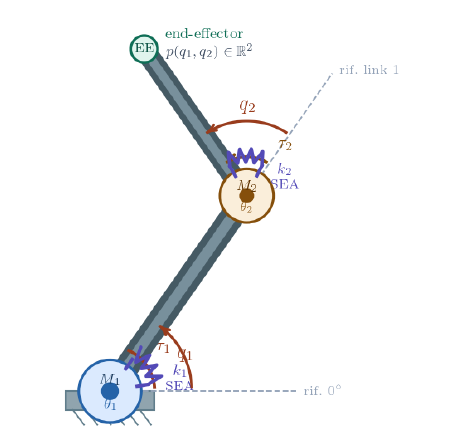

*Figura 1: Manipolatore planare *$2R$* con Series Elastic Actuators (SEA). I dischi ai giunti rappresentano i motori *$(M_1 , M_2)$* con coordinate [*$\theta_1$*, *$\theta_2$]*. Le molle angolari di rigidezza [*$k_1$*, *$k_2$]* collegano elasticamente in serie i rotori dei motori ai link corrispondenti, con coordinate articolari [*$q_1$*, *$q_2$]* .*

### Descrizione del Sistema

Si consideri un manipolatore planare a due gradi di libertà ($2R$) con attuatori elastici in serie (Series Elastic Actuators, SEA), come illustrato in figura 1. Il sistema è composto da due link rigidi di lunghezza $l_1$ e $l_2$ e massa concentrata $m_1$, $m_2$ all’estremità, collegati in serie tramite giunti rotazionali. A ciascun giunto è interposta una molla angolare di rigidezza $k_i$ che accoppia in serie il rotore del motore $i$-esimo, la cui posizione angolare è $\theta_i$ , con il link corrispondente, la cui posizione angolare è $q_i$. La deformazione elastica al giunto $i$ è $\delta_i$ = $\theta_i$ − $q_i$ .

### Dinamica del Sistema

Le equazioni del moto si suddividono in due sottosistemi accoppiati tramite la coppia elastica dei SEA. La dinamica dei link è:


$$M (q) \ddot{q} + C(q, \dot{q}) \dot{q} + G(q) = Ks (\theta - q)$$


mentre la dinamica dei motori è:


$$J_m \ddot{\theta} + B_m \dot{\theta} = \tau - K_s (\theta - q)$$


dove 

- $\tau = [\tau_1, \tau_2 ]^\top$ è il vettore delle coppie ai motori (ingressi di controllo)

- $K_s = diag[k_1 , k_2]$ è la matrice di rigidezza

- $J_m = diag[Jm_1 , Jm_2]$ inerzia

- $B_m = diag[Bm_1 , Bm_2]$ smorzamento dei motori.

### Parametri

% import
matrici_di_base

q = [pi/3 pi/3]';
dq = [0 0]';

ddq = inv(M(q))*(K(q) - C(q,dq)*dq - G(q));

model = Model(params);

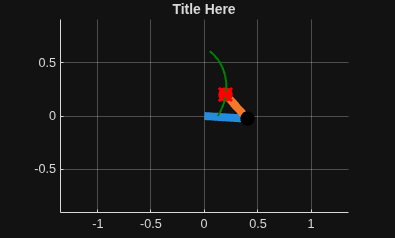

model.targetQ([.2,.2])

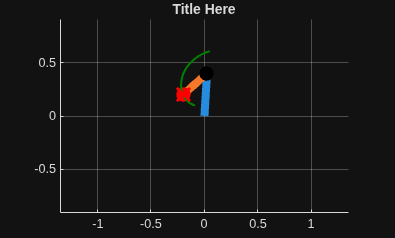

model.targetQ([-.2,.2])